# Automating Registration of Eye Scans

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

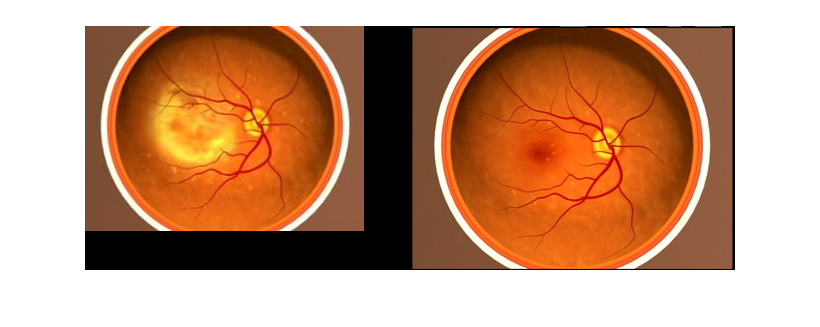

early = imread("./images/earlyAMD.jpg");
advanced = imread("./images/advancedAMD.jpg");
imshowpair(advanced, early, "montage")

## Task 1

You can use `imregcorr` to estimate the geometric transformation between images using phase correlation.

`tForm` `=` `imregcorr``(``moving``,``fixed``,``type``)`

The third input is the type of transformation passed as a string. The default is `"similarity"`

tFormAMD = imregcorr(advanced, early)

tFormAMD =   simtform2d with properties:

    Dimensionality: 2
             Scale: 1.1114
     RotationAngle: 2.4910
       Translation: [11.4231 2.0689]
                 R: [2×2 double]
                 A: [3×3 double]


## Task 2

The output of `imregcorr` is the geometric transformation. You can extract information about the geometric transformation with dot notation.

`tForm.Dimensionality`

The two properties are `Dimensionality` and the transformation matrix, `T`.

tMat = tFormAMD.T

tMat =     1.1104    0.0483         0
   -0.0483    1.1104         0
   11.4231    2.0689    1.0000


## Task 3

You can use the `imwarp` function to apply a transformation to an image.

`transformed` `=` `imwarp``(``moving``,``tForm``)``;`

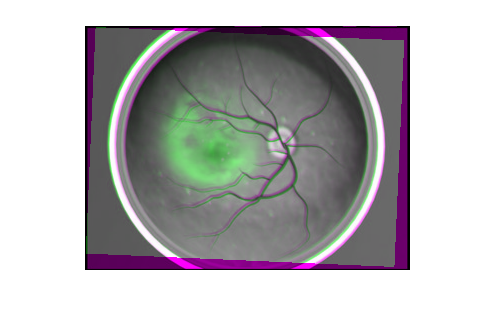

advTransform = imwarp(advanced, tFormAMD);
imshowpair(advTransform, early)